# Chapter 2. Solutions of Equations in One Variable

## 2.1 The Bisection Method

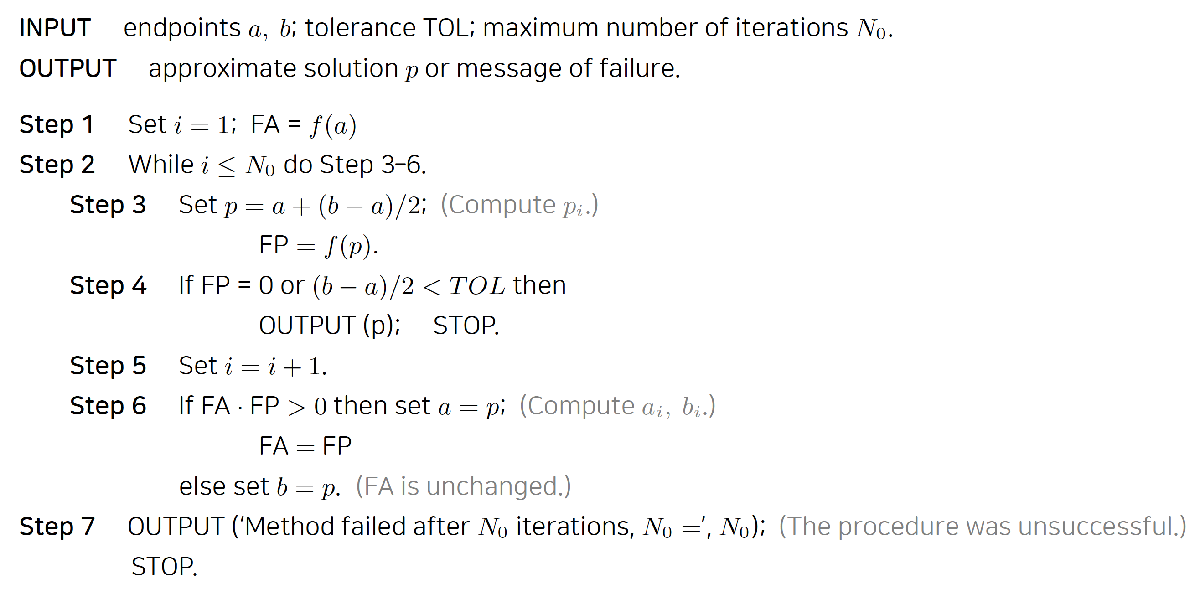

#### Example

Show that $f(x)=x^3 +4x^2 -10=0$ has a root in $\lbrack 1,2\rbrack$, and use the Bisection method to determine an approximation to the root that is accurate to at least within $10^{-4}$.

f = @(x) x^3 + 4*x^2 - 10;
a = 1;
b = 2;
TOL = 1e-4;
N0 = 30;
p = bisection(a,b,TOL,N0,f); % Complete bisection.m before you run this code.
sprintf('%.8f',p)

ans = '1.36517334'

bisection_relative_error(a,b,TOL,N0,f); % Complete bisection_relative_error.m before you run this code.

ans = 'iter	    a_n		    b_n		    p_n		 f(a_n)	    f(p_n)	    RelErr'

ans = '1	 1.000000	 2.000000	 1.500000	 -5.000	    2.375	    0.33333'

ans = '2	 1.000000	 1.500000	 1.250000	 -5.000	    -1.797	    0.20000'

ans = '3	 1.250000	 1.500000	 1.375000	 -1.797	    0.162	    0.09091'

ans = '4	 1.250000	 1.375000	 1.312500	 -1.797	    -0.848	    0.04762'

ans = '5	 1.312500	 1.375000	 1.343750	 -0.848	    -0.351	    0.02326'

ans = '6	 1.343750	 1.375000	 1.359375	 -0.351	    -0.096	    0.01149'

ans = '7	 1.359375	 1.375000	 1.367188	 -0.096	    0.032	    0.00571'

ans = '8	 1.359375	 1.367188	 1.363281	 -0.096	    -0.032	    0.00287'

ans = '9	 1.363281	 1.367188	 1.365234	 -0.032	    0.000	    0.00143'

ans = '10	 1.363281	 1.365234	 1.364258	 -0.032	    -0.016	    0.00072'

ans = '11	 1.364258	 1.365234	 1.364746	 -0.016	    -0.008	    0.00036'

ans = '12	 1.364746	 1.365234	 1.364990	 -0.008	    -0.004	    0.00018'

ans = '13	 1.364990	 1.365234	 1.365112	 -0.004	    -0.002	    0.00009'

## 2.2 Fixed-Point Iteration

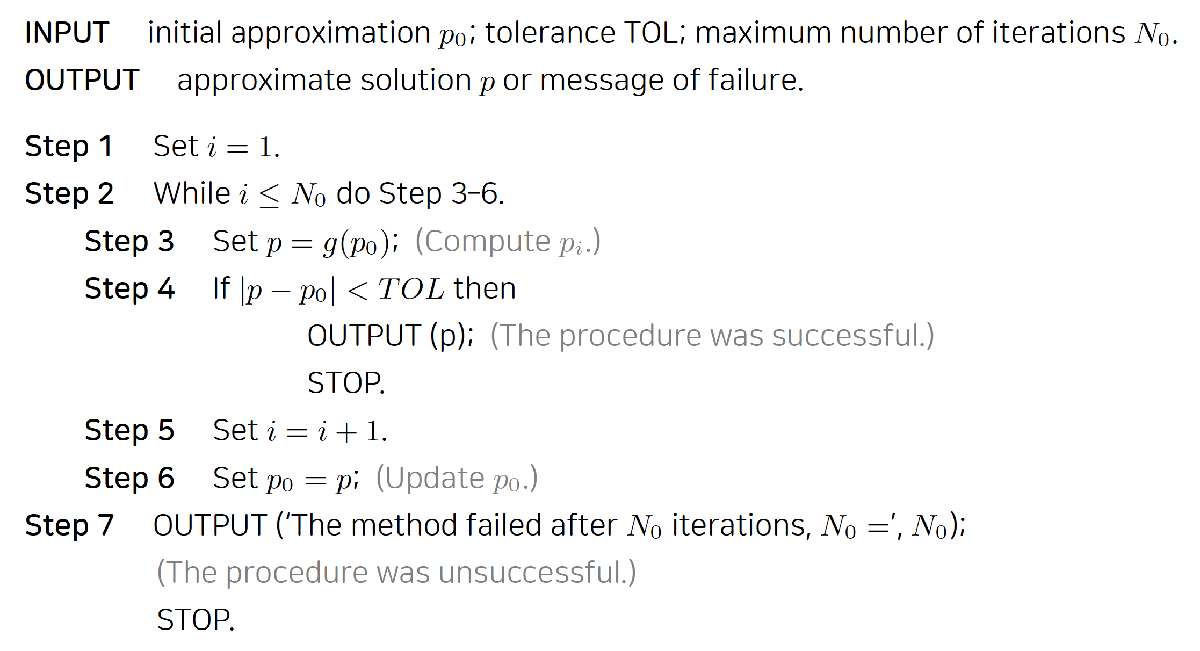

#### Example

The equation $x^3 +4x^2 -10=0$ has a unique root in [1,2]. Its value is approximately 1.365230013.


$$\left(a\right)\;\;\;\;\;x=g_1 \left(x\right)=x-x^3 -4x^2 +10$$



$$\left(b\right)\;\;\;\;\;x=g_2 \left(x\right)={\left(\frac{10}{x}-4x\right)}^{\frac{1}{2}}$$



$$\left(c\right)\;\;\;\;\;x=g_3 \left(x\right)=\frac{1}{2}{\left(10-x^3 \right)}^{\frac{1}{2}}$$



$$\left(d\right)\;\;\;\;\;x=g_4 \left(x\right)={\left(\frac{10}{4+x}\right)}^{\frac{1}{2}}$$



$$\left(e\right)\;\;\;\;\;x=g_5 \left(x\right)=x-\frac{x^3 +4x^2 -10}{3x^2 +8x}$$


p0 = 1.5;
TOL = 1e-9;
N0 = 50;

(a)

g1 = @(x) x - x^3 - 4*x^2 + 10;
fixed_point(p0,TOL,N0,g1); % Complete fixed_point.m before you run this code.

ans = 'iteration 0: 1.500000000'

ans = 'iteration 1: -0.875000000'

ans = 'iteration 2: 6.732421875'

ans = 'iteration 3: -469.720012002'

ans = 'iteration 4: 102754555.187385112'

ans = 'iteration 5: -1084933870531746486812672.000000000'

ans = 'iteration 6: 1277055591444378466573438322982097922987374859897466271890545849990643712.000000000'

ans = 'iteration 7: -2082712908581027140718627596215125198233566834955693738186359378372116057292259890311226411168586473990737217273401843816752280680672161989639911787609956906414784487338066489602776531929857389090717236430155817156608.000000000'

ans = 'iteration 8: NaN'

ans = 'iteration 9: NaN'

ans = 'iteration 10: NaN'

ans = 'iteration 11: NaN'

ans = 'iteration 12: NaN'

ans = 'iteration 13: NaN'

ans = 'iteration 14: NaN'

ans = 'iteration 15: NaN'

ans = 'iteration 16: NaN'

ans = 'iteration 17: NaN'

ans = 'iteration 18: NaN'

ans = 'iteration 19: NaN'

ans = 'iteration 20: NaN'

ans = 'iteration 21: NaN'

ans = 'iteration 22: NaN'

ans = 'iteration 23: NaN'

ans = 'iteration 24: NaN'

ans = 'iteration 25: NaN'

ans = 'iteration 26: NaN'

ans = 'iteration 27: NaN'

ans = 'iteration 28: NaN'

ans = 'iteration 29: NaN'

ans = 'iteration 30: NaN'

ans = 'iteration 31: NaN'

ans = 'iteration 32: NaN'

ans = 'iteration 33: NaN'

ans = 'iteration 34: NaN'

ans = 'iteration 35: NaN'

ans = 'iteration 36: NaN'

ans = 'iteration 37: NaN'

ans = 'iteration 38: NaN'

ans = 'iteration 39: NaN'

ans = 'iteration 40: NaN'

ans = 'iteration 41: NaN'

ans = 'iteration 42: NaN'

ans = 'iteration 43: NaN'

ans = 'iteration 44: NaN'

ans = 'iteration 45: NaN'

ans = 'iteration 46: NaN'

ans = 'iteration 47: NaN'

ans = 'iteration 48: NaN'

ans = 'iteration 49: NaN'

ans = 'iteration 50: NaN'

ans = 'Method failed after N0 iterations, N0 = 50'

(b)

g2 = @(x) sqrt(10/x - 4*x);
fixed_point(p0,TOL,N0,g2); % Complete fixed_point.m before you run this code.

ans = 'iteration 0: 1.500000000'

ans = 'iteration 1: 0.816496581'

ans = 'iteration 2: 2.996908806'

ans = 'iteration 3: 0.000000000'

ans = 'iteration 4: 2.753622388'

ans = 'iteration 5: 1.814991519'

ans = 'iteration 6: 2.384265848'

ans = 'iteration 7: 2.182771900'

ans = 'iteration 8: 2.296997587'

ans = 'iteration 9: 2.256510286'

ans = 'iteration 10: 2.279179049'

ans = 'iteration 11: 2.271142587'

ans = 'iteration 12: 2.275631311'

ans = 'iteration 13: 2.274039927'

ans = 'iteration 14: 2.274928362'

ans = 'iteration 15: 2.274613384'

ans = 'iteration 16: 2.274789213'

ans = 'iteration 17: 2.274726876'

ans = 'iteration 18: 2.274761673'

ans = 'iteration 19: 2.274749337'

ans = 'iteration 20: 2.274756223'

ans = 'iteration 21: 2.274753782'

ans = 'iteration 22: 2.274755145'

ans = 'iteration 23: 2.274754661'

ans = 'iteration 24: 2.274754931'

ans = 'iteration 25: 2.274754835'

ans = 'iteration 26: 2.274754889'

ans = 'iteration 27: 2.274754870'

ans = 'iteration 28: 2.274754880'

ans = 'iteration 29: 2.274754877'

ans = 'iteration 30: 2.274754879'

ans = 'iteration 31: 2.274754878'

ans = 'iteration 32: 2.274754878'

ans = 'iteration 33: 2.274754878'

ans = 'iteration 34: 2.274754878'

ans = 'iteration 35: 2.274754878'

ans = 'iteration 36: 2.274754878'

ans = 'iteration 37: 2.274754878'

ans = 'iteration 38: 2.274754878'

ans = 'iteration 39: 2.274754878'

ans = 'iteration 40: 2.274754878'

ans = 'iteration 41: 2.274754878'

ans = 'iteration 42: 2.274754878'

ans = 'iteration 43: 2.274754878'

ans = 'iteration 44: 2.274754878'

ans = 'iteration 45: 2.274754878'

ans = 'iteration 46: 2.274754878'

ans = 'iteration 47: 2.274754878'

ans = 'iteration 48: 2.274754878'

ans = 'iteration 49: 2.274754878'

ans = 'iteration 50: 2.274754878'

ans = 'Method failed after N0 iterations, N0 = 50'

ans = 2.2748 - 3.6088i

(c)

g3 = @(x) 0.5 * sqrt(10 - x^3);
fixed_point(p0,TOL,N0,g3); % Complete fixed_point.m before you run this code.

ans = 'iteration 0: 1.500000000'

ans = 'iteration 1: 1.286953768'

ans = 'iteration 2: 1.402540804'

ans = 'iteration 3: 1.345458374'

ans = 'iteration 4: 1.375170253'

ans = 'iteration 5: 1.360094193'

ans = 'iteration 6: 1.367846968'

ans = 'iteration 7: 1.363887004'

ans = 'iteration 8: 1.365916733'

ans = 'iteration 9: 1.364878217'

ans = 'iteration 10: 1.365410061'

ans = 'iteration 11: 1.365137821'

ans = 'iteration 12: 1.365277209'

ans = 'iteration 13: 1.365205850'

ans = 'iteration 14: 1.365242384'

ans = 'iteration 15: 1.365223680'

ans = 'iteration 16: 1.365233256'

ans = 'iteration 17: 1.365228353'

ans = 'iteration 18: 1.365230863'

ans = 'iteration 19: 1.365229578'

ans = 'iteration 20: 1.365230236'

ans = 'iteration 21: 1.365229899'

ans = 'iteration 22: 1.365230072'

ans = 'iteration 23: 1.365229984'

ans = 'iteration 24: 1.365230029'

ans = 'iteration 25: 1.365230006'

ans = 'iteration 26: 1.365230017'

ans = 'iteration 27: 1.365230011'

ans = 'iteration 28: 1.365230014'

ans = 'iteration 29: 1.365230013'

ans = 'iteration 30: 1.365230014'

(d)

g4 = @(x) sqrt(10/(4+x));
fixed_point(p0,TOL,N0,g4); % Complete fixed_point.m before you run this code.

ans = 'iteration 0: 1.500000000'

ans = 'iteration 1: 1.348399725'

ans = 'iteration 2: 1.367376372'

ans = 'iteration 3: 1.364957015'

ans = 'iteration 4: 1.365264748'

ans = 'iteration 5: 1.365225594'

ans = 'iteration 6: 1.365230576'

ans = 'iteration 7: 1.365229942'

ans = 'iteration 8: 1.365230023'

ans = 'iteration 9: 1.365230012'

ans = 'iteration 10: 1.365230014'

ans = 'iteration 11: 1.365230013'

(e)

g5 = @(x) x - (x^3 + 4*x^2 - 10)/(3*x^2 + 8*x);
fixed_point(p0,TOL,N0,g5); % Complete fixed_point.m before you run this code.

ans = 'iteration 0: 1.500000000'

ans = 'iteration 1: 1.373333333'

ans = 'iteration 2: 1.365262015'

ans = 'iteration 3: 1.365230014'

ans = 'iteration 4: 1.365230013'

## 2.3 Newton's Method and Its Extensions

### Newton's Method

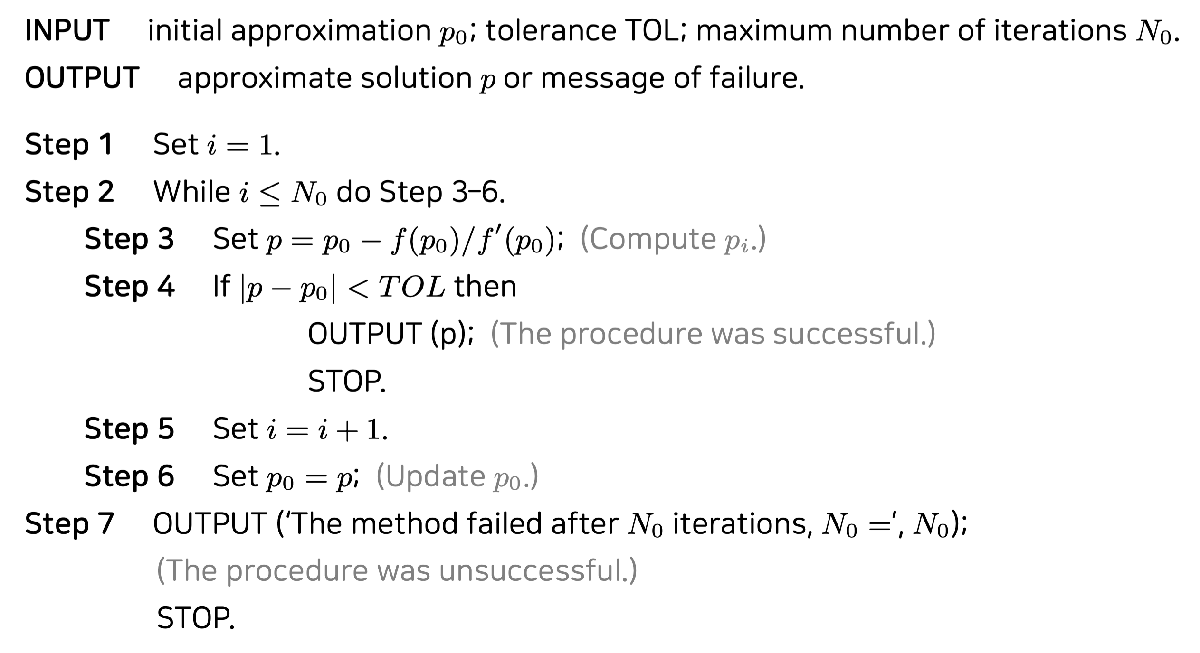

#### Example

Consider the function $f\left(x\right)=\cos \;x-x=0$. Approximate a root of $f$ using Newton's Method.	

f = @(x) cos(x) - x;
fp = @(x) -sin(x) - 1;
p0 = pi/4;
TOL = 1e-8;
N0 = 10;

newton(p0, TOL, N0, f, fp); % Complete newton.m before you run this code.

ans = 'iteration 1: p = 0.73953613	 |p - p0| = 0.04586203'

ans = 'iteration 2: p = 0.73908518	 |p - p0| = 0.00045096'

ans = 'iteration 3: p = 0.73908513	 |p - p0| = 0.00000004'

ans = 'iteration 4: p = 0.73908513	 |p - p0| = 0.00000000'

### Secant Method

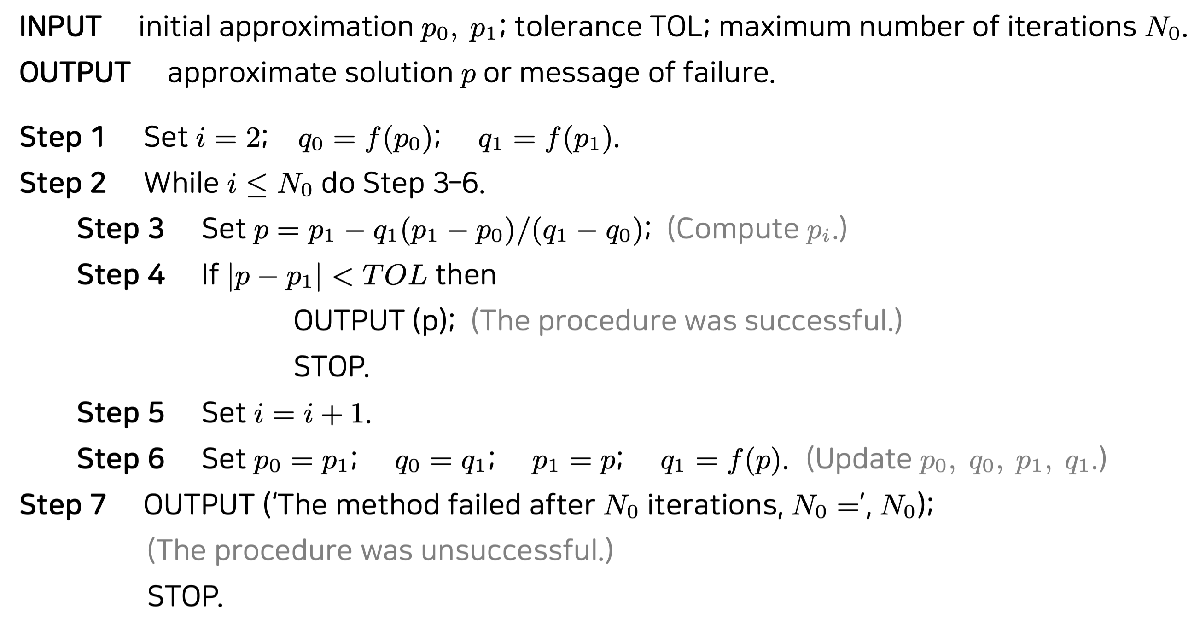

#### Example

Consider the function $f\left(x\right)=\cos \;x-x=0$. Approximate a root of $f$ using the Secant Method.	

f = @(x) cos(x) - x;
p0 = 0.5;
p1 = pi/4;
TOL = 1e-8;
N0 = 10;

secant(p0, p1, TOL, N0, f); % Complete secant.m before you run this code.

ans = 'iteration 2: p = 0.736384139	 |p - p1| = 0.0490140246'

ans = 'iteration 3: p = 0.739058139	 |p - p1| = 0.0026740004'

ans = 'iteration 4: p = 0.739085149	 |p - p1| = 0.0000270101'

ans = 'iteration 5: p = 0.739085133	 |p - p1| = 0.0000000161'

ans = 'iteration 6: p = 0.739085133	 |p - p1| = 0.0000000000'